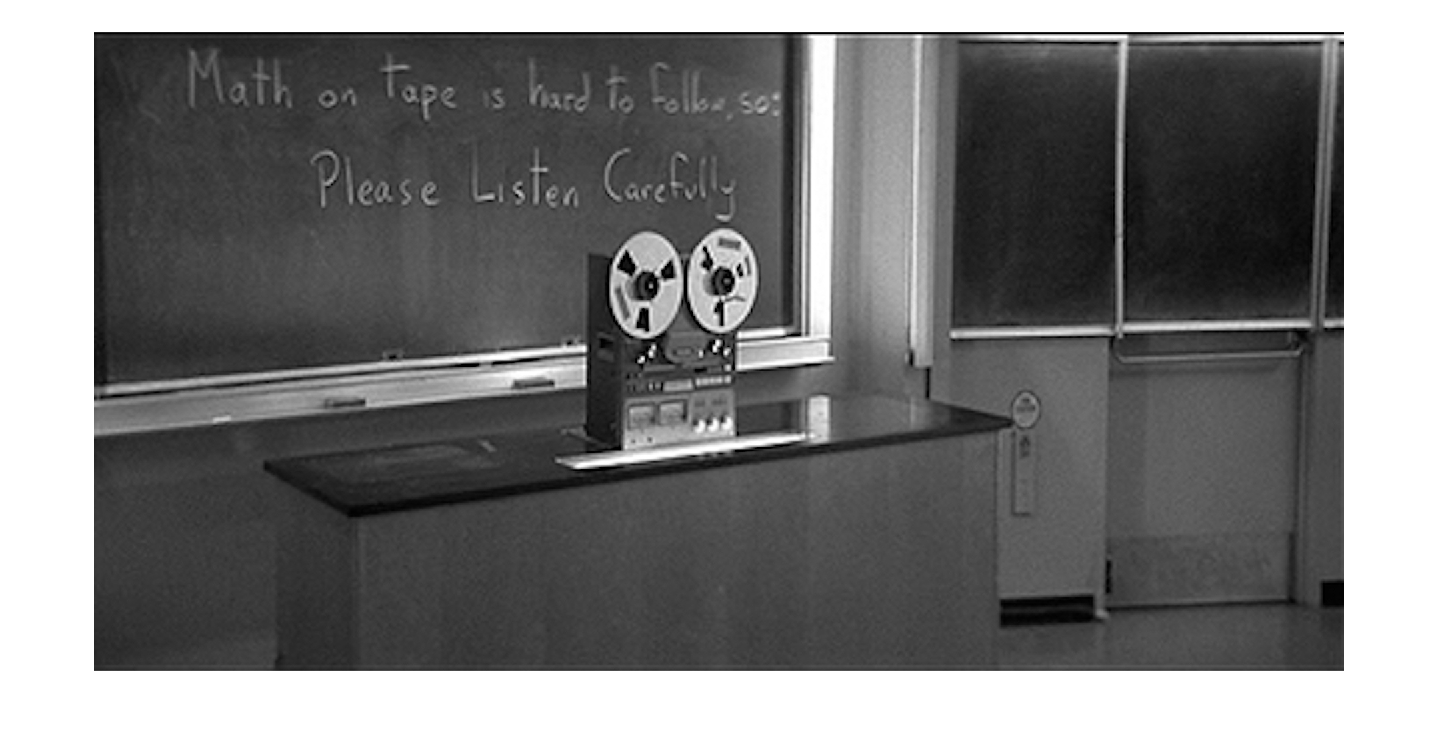

clear;clc;

img = rgb2gray(imread('images/recorder.jpg'));
figure(1);
imshow(img);

## Image Compression with L2 Norm

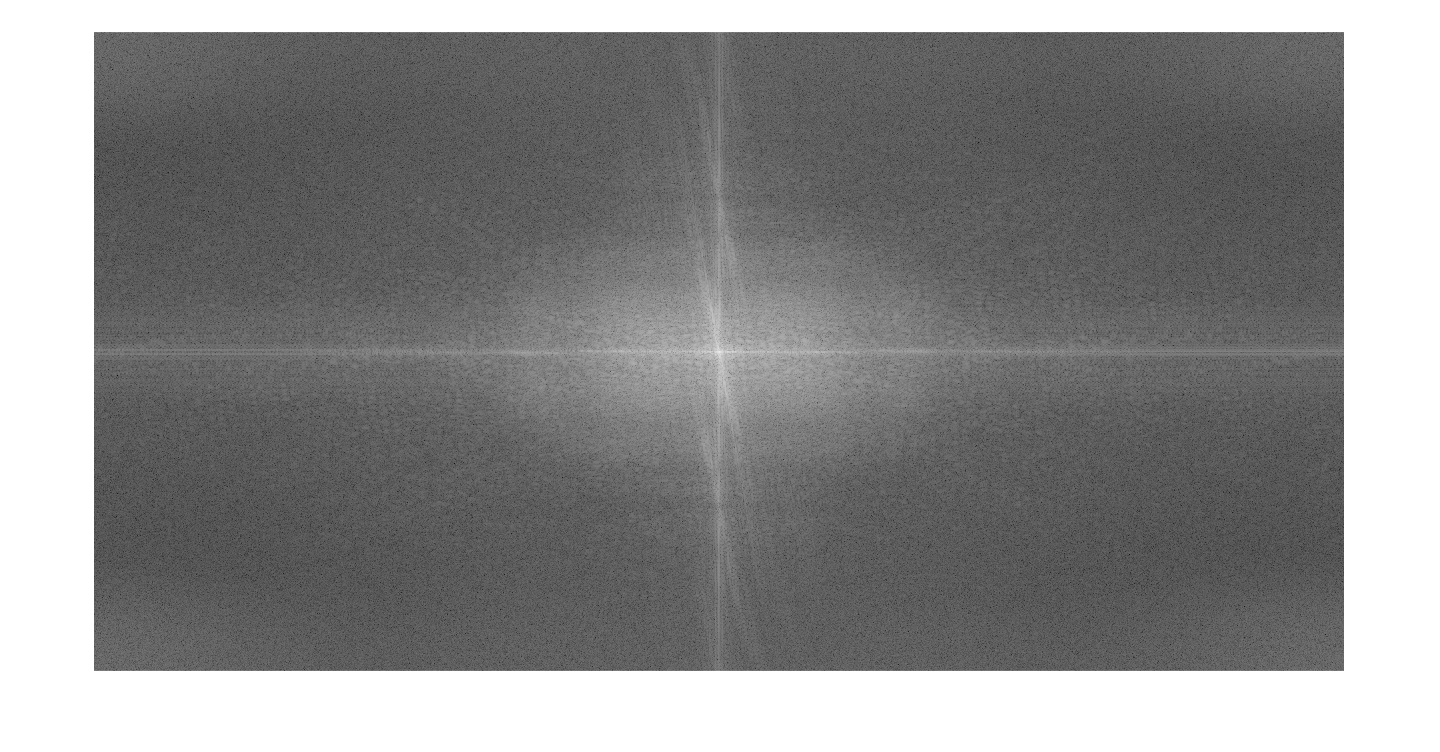

img_w = fft2(img); % get the FFT
shifted_w = fftshift(img_w);
img_freq = log(1+abs(shifted_w));
figure(2);
imshow(img_freq/(max(max(img_freq)-min(min(img_freq)))));

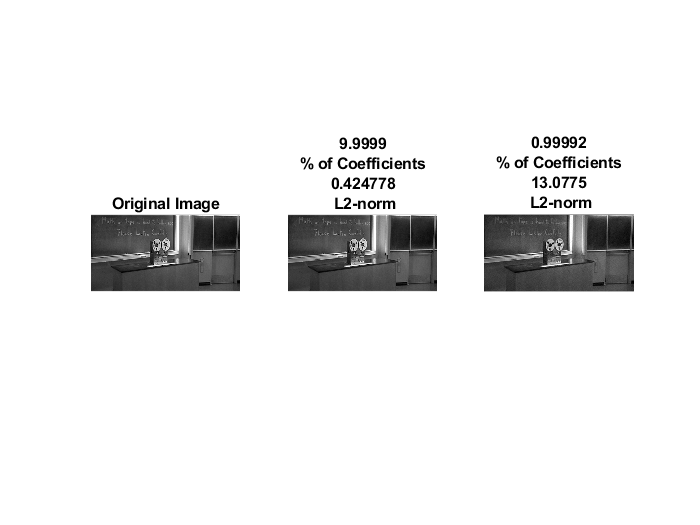

figure(3), subplot(1, 3, 1), imshow(img);
title('Original Image','FontSize',10);
drawnow;
pic_count = 2;
thresh_arr = [prctile(abs(img_w),90,'all') prctile(abs(img_w),99,'all')];
for thresh = thresh_arr
    ind = abs(img_w)>thresh;
    img_w_comp = img_w.*ind;    
    img_comp = uint8(ifft2(img_w_comp));
    count = sum(sum(ind));
    [nrows, ncols] = size(ind);
    percent = count*100/(nrows*ncols);
    l2norm = sum(sum((img-img_comp).^2))/(nrows*ncols);
    figure(3), subplot(1, 3, pic_count), imshow(img_comp);
    title({num2str(percent) '% of Coefficients', l2norm ' L2-norm'},'FontSize',2);
    drawnow;
    pic_count = pic_count + 1;
end